**Exercise 2 **

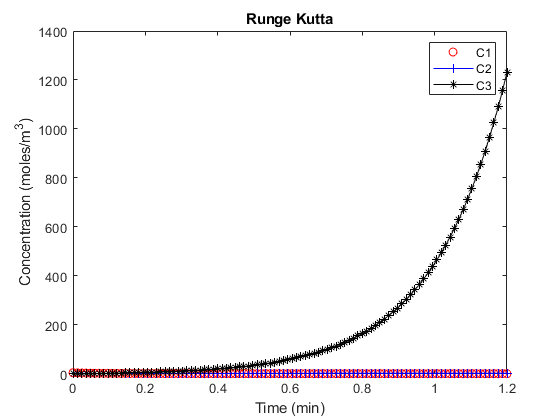

t=linspace(0,1.2);
C=[5; 3; 0]; 
g=@odesyst2;
[result]=runge_kutta(g,t,C);
C1 = result(1,:);
C2 = result(2,:);
C3 = result(3,:);
plot(t,C1,'ro',t,C2,'-b+',t,C3,'-k*')
title('Runge Kutta')
xlabel('Time (min)')
ylabel('Concentration (moles/m^3)')
legend('C1','C2','C3');

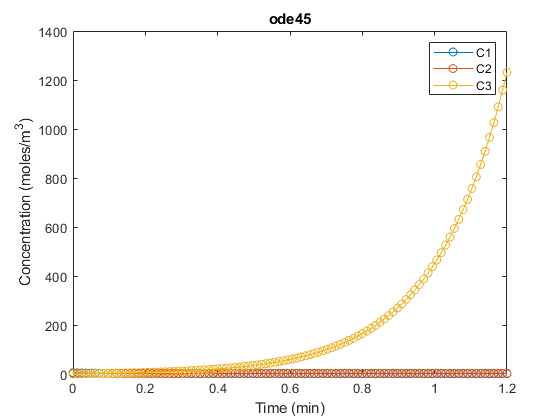

ode45(g,t,C)
title('ode45')
xlabel('Time (min)')
ylabel('Concentration (moles/m^3)')
legend('C1','C2','C3');

ode45 and runge_kutta give the same result. 

Solving the ode system using ode45 and ode23s with $\alpha_1 =100000,\alpha_2 =1,\alpha_3 =10$.

[c]=runge_kutta(@odesyst,t,C)

c = 	1.0e+22 *

    0.0000   -2.1851      -Inf       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0000   -0.0000      -Inf       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   

Using Rungw Kutta does not work for n=4. For n=100 it will also not work because we have a stiff ode system.

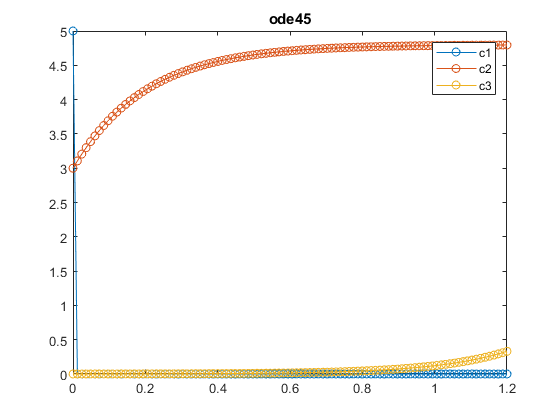

t=linspace(0,1.2);
C=[5; 3; 0]; 
ode45(@odesyst,t,C)
title('ode45')
legend('c1','c2','c3')

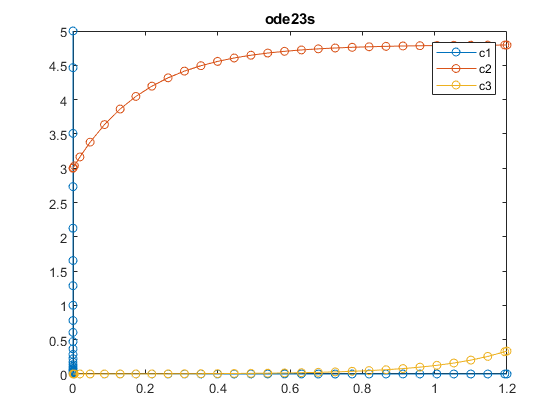

ode23s(@odesyst,[0 1.2],C)
title('ode23s')
legend('c1','c2','c3')

It took 6 seconds for ode45 to run. In contrast, ode23s took 0.41 seconds.

function [dcdt] = odesyst(t,c)
c01=3.2;c02=4.8;Q=10; V=2;
dcdt=zeros(3,1);
dcdt(1)=(Q/V)*(c01-c(1))-100000*c(1)*c(2);
dcdt(2)=(Q/V)*(c02-c(2))-1*c(1)*c(2);
dcdt(3)=(Q/V)*c(3)+10*c(1)*c(2);
end
function [dcdt] = odesyst2(t,c)
c01=3.2;c02=4.8;Q=10; V=2;
dcdt=zeros(3,1);
dcdt(1)=(Q/V)*(c01-c(1))-2.5*c(1)*c(2);
dcdt(2)=(Q/V)*(c02-c(2))-2.5*c(1)*c(2);
dcdt(3)=(Q/V)*c(3)+2.5*c(1)*c(2);
end



function [y] = runge_kutta(df,x,y0)
m = length(y0);
n = length(x);
% y is a matrix of size 'mxn'
y=zeros(m,n);
y(:,1)=y0;
for i=1:n-1
    h = x(i+1)-x(i);
    xi=x(i);
    yi=y(:,i);
    k1 = feval(df,xi,yi);
    k2 = feval(df,xi+0.5*h,yi+0.5*k1*h);
    k3 = feval(df,xi+0.5*h,yi+0.5*k2*h);
    k4 = feval(df,xi+h,yi+k3*h);
    y(:,i+1) = y(:,i) + h*(k1+2*k2+2*k3+k4)/6;
end
end
